# `BIOM9660 LABORATORY 2024: INTRODUCTION TO SOUND PROCESSING IN COCHLEAR IMPLANTS`

## `Introduction:`

`By now you should appreciated that building an implantable bionic device is only part of the work that must be done for patients to gain benefit from the device. The question of what to do with the implant once it is implanted is extraordinarily important. This is true for all bionic devices, irrespective of their application. In this introductory laboratory, we will explore sound processing for the cochlear implant which, as you heard this week, is extremely vital for its functioning.`

`For many years, multichannel cochlear implants for the hearing impaired have remained largely the same in terms of their hardware components. While they are much more sophisticated in terms of software compared to previous devices and even have features such as reverse telemetry and mechanisms to record the neural responses they elicit, they remain with the same number of stimulation channels as they had two decades ago. Electrically, they behave almost unchanged in their stimulus waveforms.`

`But in stark contrast to the electrical behaviour of cochlear implants, the nature of how this electrical behaviour is utilised and how sound is processed before it takes the form of electrical pulses, has changed significantly over this same period. Indeed, the same 20-year-old implanted device can now be "instructed" with new software to give electrical stimulation that delivers information to the auditory system with truly remarkable results. Where once the ability to converse over the telephone using a cochlear implant was rare, it is now commonplace. In fact, as you now know, modern implants can now even be controlled using a smartphone and even the audio from the phone can be directly streamed to the implant. The changes that have taken place are largely to do with sound processing that happens within the speech processor. An introduction to this vast field of research is the subject of this laboratory – that is, how does one take sound and turn it into electrical stimulation patterns? This week, Dr Swanson gave us some good insights on how a normal ear processes sounds and how a cochlear implant tries to mimic the various elements of processing (i.e. filtering, loudness etc). In this lab we will endeavour to conduct some of that processing on some real sound files. The sole purpose of this lab is for ``YOU`` to individually understand the concepts and some nuances of sound processing and see for yourself the effects of various processes can affect the output. While many lines of code have been written for you in this lab, you will need to fill in the missing bits and then view the output/errors for further understanding. ``Therefore,`` i``t is imperative that you understand how each section of the code functions by running each section of the code and viewing the results before you move on to the next section``. ``Understanding the concepts of sound processing as well as the different strategies to do so will significantly help you complete the assignment.`

## `Part A: Exploring Frequencies Sampling and the Nyquist Rate:`

`The healthy, young, human ear can resolve frequencies within a range of roughly 20 to 20,000 cycles per second (Hertz or Hz). As we grow older, our ability to hear the extremes of this range diminish. Students of mathematics will recall the 'fast fourier transform' (FFT) which allows for the transformation of time-domain signals such as a '.WAV' sound recording which, if plotted, would typically be expressed in terms of amplitude and time in the time-domain. A frequency-domain plot after performing an FFT operation will show how much energy within a signal (e.g. the same '.WAV' file as before) comes from a particular frequency or frequencies. For a pure frequency (e.g. a sinusoid at a particular, constant frequency), the frequency-domain plot will show only one frequency as the contributor to the signal. A sound such as the word, “Hello” will contain many frequencies simultaneously and is a combination of multiple pure frequencies occurring at once.`

### `Procedure:`

`Your first task is to complete a script to produce a pure, 5 Hz sinusoidal signal that lasts for two seconds.` 

`Write the bit of code below in the space provided that is required for signal x to be a sine wave. When you have filled in the missing line, hit the "Run this Section" button. Vary the frequency and sampling rate while observing what happens to the signal in the output below the code. `

 
% signal frequency
frequency = 5; % in Hz
% duration of the signal
duration = 2; % in seconds
% Sampling frequency (the number of datapoints per second) 
fs = 10; % in Hz
% Set up a time vector with the correct number of data points 
time = (0:1/fs:duration);
% Write the bit of code below to create the sinusoid signal x
x = ;

Invalid expression. Check for missing or extra characters.

plot(time,x,'-x');
xlabel('Time (s)');
ylabel('Amplitude');
title('TIME DOMAIN PLOT OF PURE FREQUENCY SIGNAL');

`Once you have finished playing with the code and are happy with your plot, click on the plot and open it in a new figure window (click the curved arrow on the top right of the plot), then save the plot somewhere you can access it later.`

# `Think about what you've just observed and type in answers to the following questions. `

# `1) Did you use the 'sin' or 'cos' function to generate the sine wave?`

# `Answer``:`

# `2) If you used the 'sin' function, what did you observe when the sampling rate was twice the desired frequency (Nyquist rate)? Try using the 'cos' function. What is different about this?`

# `Answer``:`

# `3) Save some plots using any 4 different sampling rates of your choice for a fixed wave frequency. Go above and below the nyquist rate. Note down your observations for the different sampling rates below.`

# `Answer``:`

# `4) BONUS - Did you observe a different behaviour when using the 'sin' and 'cos' functions to generate the sine wave? If so, why?`

# `Answer``:`

### `Making Sound:`

`What you have observed in the exercise above highlights the Nyquist Rate – that is, the rate at which a digital system must sample a signal in order to unambiguously resolve all elements of the signal (cycles of the sinusoid in this case). The Nyquist rate is twice the frequency of a given signal (or the highest frequency of the signal). `

`Sampling at the Nyquist rate doesn't guarantee a reconstruction of the signal, it only guarantees that you won't miss the number of cycles. In fact, unless the sampling frequency is infinite, any attempts at reconstruction of an original, non-trivial waveform will result only in an approximation of that signal. In practice, it is beneficial to sample at a rate at least 2.5 times the highest frequency of interest but obviously if you can go higher, no harm to ensure adequate reconstruction. You may have also noticed that distortion can still occur at certain combinations of frequencies and sampling rates even when the Nyquist rate is satisfied. For example, note that when fs = 10 Hz and frequency = 5 Hz, the sinusoidal shape is lost but each cycle can be detected when using the 'cos' function (The 'sin' function requires an even higher sampling rate as it starts off from zero. sin(0) = 0 whereas cos(0) = 1!). `

`As noted above, a normally-hearing human can hear frequencies between (roughly) 20 and 20,000 Hz. In order to be able to capture the 20 kHz frequencies, the sound must be sampled at (at least) 40 kHz. Ever wonder why compressed music files (e.g. 'MP3s') are often sampled at 44 kHz? Speech signals tend to only contain frequencies up to ~8,000Hz. This is why the cochlear implant filter bank does not need to sample all frequencies of human hearing. Depending on the frequency of the sinusoid we made above, if it were to be fed into a speaker, our ability to hear it would depend on our own hearing range. We will now make a sound that we (hopefully) can hear.`

### `Procedure:`

`The script below will produce a signal of two seconds duration at a pure frequency of 4 kHz sampled at 44 kHz. Plot and save the first 5 ms of the signal as a time-domain waveform. Save the sound as a ‘.WAV’ file. Play the sound in a media player or equivalent but try not to annoy your neighbours if you are in the lab. Remember you must fill all missing bits in the code to produce a clean output. Remember to save your plot once you are happy with it.`

%Write your script below. Feel free to copy parts of the script from above

 
% signal frequency
frequency = 4000; % in Hz
% duration of the signal
duration = 2; % in seconds
% Sampling frequency (the number of datapoints per second) 
fs = 44000; % in Hz
% Set up a time vector with the correct number of data points 
time = (0:1/fs:(duration-1/fs));
% Create the sinusoid signal x - write a line of code below
x = ;
% write two lines of code to plot x and limit the axes so that you can clearly view the individual cycles in the plot 

xlabel('Time (s)');
ylabel('Amplitude');
title('TIME DOMAIN PLOT OF 4 kHz SIGNAL');
%write a line of code to save x as a .wav file


`You next task is to find the frequency spectrum by taking the ``absolute value`` of the fourier transform of the sound vector x, plot it and save it. This is because FFT will produce a complex number. Taking the absolute value will only consider the magnitude of the FFT.`

 
%Write few lines of code here to compute the fft and plot it .. Dont forget labels and
%axes limits


`The fast fourier transform (FFT) produces real and imaginary components. As such, the ``magnitude ``of the signal (the square root of the sum of the squares of the real and imaginary parts of the FFT) is capable of being plotted on a simple 2D plot. Plotting as-is will produce a plot with units of “FFT magnitude” and “sample number”. Since “sample number” isn’t particularly meaningful, this should be changed to something more sensible. What the FFT really contains is the contribution each frequency makes towards the overall sound. Therefore, scaling the horizontal axis to read “frequency” instead of “sample number” makes a great deal more sense. The sampling frequency, ‘fs’ has units of samples per second. Each element of the FFT has units of cycles per sample. Multiplying these causes “samples” to cancel, leaving behind cycles per second or Hz.`

# `Think about what you've just observed and type in answers to the following questions. `

# `1) What is the peak frequency of the sound? `

# `Answer``:`

# `2) Did you only see one peak or more in the FFT? Why?`

# `Answer``:`

## `Part B: Formants`

`What is a formant?`

`The Fourier analysis illustrated in the sections above is problematic in capturing the relevant features of speech because it not only requires a relatively large sample, but it also fails to find time-varying parameters that make up the subtleties of speech. Therefore, simply extracting the peak frequencies of a given signal in its entirety provides insufficient information to represent the original sound unless it is a pure sound as we have seen above. Another way is needed.`

`If one were to construct a model of the human speech system, the logical approach would be to find a source of vibration to represent the glottis – an electronic buzzer for instance, and place this buzzer at one end of a tube to represent the vocal tract. The tube would ideally be of a soft and bendable material so that its geometry could be subtly changed to represent movements of the mouth, tongue, and lips. The buzzer would ideally have the capacity to change its intensity and frequency to replicate the glottis' capabilities. As the buzzer "buzzes" and sound is emitted from the tube, there are resonant frequencies which characterise the sound. These resonant frequencies are referred to as ``formants``. Remember the 'asa' sound in Dr Swanson's lecture? The way we'll use to discover the formants of a sound is by way of a filtering technique called linear prediction which, conveniently, is contained within the ``lpc() ``function available in Matlab. Suffice for the purposes of this laboratory, we shall use this function as a tool to find the formants of our sound and not delve further into the issue. Should you wish to explore speech analysis in more detail, a more thorough study of linear prediction methods would be a good place to start [1,2].`

`References:`

`[1] Atal, B. S. and Hanauer, S. L. (1971) "Speech Analysis and Synthesis by Linear Prediction of the Speech Wave", J. Acoust. Soc. Am., 50, 637-655.`

`[2] J.D.Markel and A.H.Gray, 1976, Linear prediction of speech, Springer-Verlag, Berlin, 1976`

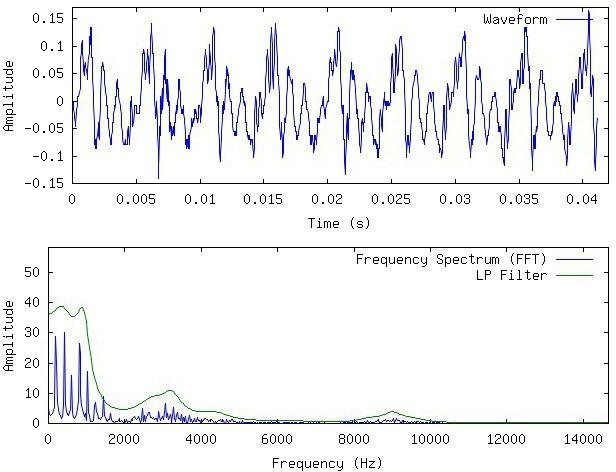

`The vowel sound “a” (as in “say”) is shown in the figure above. In the upper panel, the time- domain signal is shown. In the lower panel, the frequency-domain signal (FFT) is shown (the jagged signal with many peaks and troughs) along with a smooth, linear prediction coefficient filter plot with some distinctive peaks at 350.4, 951.3, 2626.8, 3253.7, 4423.7, etc. and another at about 9 kHz. These peaks (some of which are rather subtle) are known as the formant frequencies and are referred to as f1, f2, etc. The essence of the sound can be extracted from these formants and it is these formants that can be used to decide the frequency content of the signal that has to be delivered by the cochlear implant. Another parameter F0 is the overall vibration rate of the vocal chords and will not be used here.`

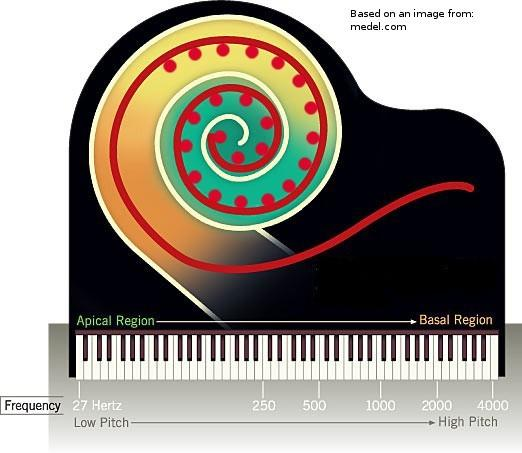

`Recall that cochlear implants are 'tonotopically mapped' – that is, the position of each electrode within the cochlea corresponds to a particular frequency range as depicted in the diagram above. In the FFT figures above, the horizontal axis could be divided into several frequency ranges, each range (with some overlap between them) would represent the location of stimulation covered by a single electrode within the cochlea. While modern speech processing techniques are much more sophisticated than what we will explore here, the basics are:`

- `Formants correspond to electrodes.`

- `By determining the formants of a given sound, the formants may be 'mapped' to individual electrodes for stimulation.`

- `The charge to be delivered by the stimulus can be determined by the amplitude of the envelope of the original signal such as in the CIS strategy or the energy of the signal passed by each filter bank when choosing a subset of banks (such as in the SPEAK or ACE strategy).`

### `Procedure:`

`On the BIOM9660 Moodle in the laboratories section, there are several sounds available for you to use in “.wav” format. Choose one (or more) of these for use in exploring formants in the next steps of this laboratory. To read a '.wav' file sound, run the following code. Be sure to replace 'filename.wav' with the file of your choice. Write your own code to plot and label the time-domain signal. Be sure to save the plot.`

 
% clear memory in case matrices are already defined – very important!!! 
clear;
% read the .wav file; x = waveform vector; fs = sampling frequency 
[x, fs] = audioread('filename.wav');
% Make sure that the file is in the correct format before proceeding 
[n, nChan]=size(x);
if nChan > 1
    fprintf('The type of the wave file must be mono (not stereo)\n');
    fprintf('Converting matrix to mono now ...\n');
    x(:,2) = [];
end
time = (0:1/fs:(n-1)/fs);
%write code below to plot the signal in the time domain ... label plot

## `PART C: Epochs`

`In the previous section, you imported an entire .wav sound and plotted its time-domain signal. Some of these sounds are quite long in length. As sound is a dynamic flow of changing frequencies over time, we cannot represent an entire sound all at once with the formants and expect to glean much (or any) useful information from it. As such, we need to consider small time-steps or epochs or frames of a given sound, find the formants of each epoch, and deliver the important features of the sound within each epoch to a speaker or a cochlear implant in a step-wise fashion.`

`The sounds available on the BIOM9660 Moodle are typically two seconds in duration. If we (somewhat arbitrarily) choose 20 ms to be our epoch, then we will have 100 epochs within our two- second sound. The objective of this section of the laboratory is to divide the sound into 100 epochs, determine the formant frequencies for each epoch, and reconstruct the sound using only formant frequencies. Note that for a two second sound sampled at 44 kHz, each epoch will have 880 samples. As all this is duration dependent, the number of samples per epoch might differ between the different sounds.`

`Break up the sound into 100 epochs by writing code below. Some code has been written for you. Plot and label the 50th epoch (i.e. somewhere in the middle of the sound).`

 
% How many epochs?
N=100 ;
% How many datapoints in each epoch? 
points_per_epoch = length(x)/N;
% Ditch any decimals if length(x)/N is not an integer 
points_per_epoch = floor(points_per_epoch);
epoch = zeros(points_per_epoch,N);
for i=1:N
    % form an epoch
    %Write this bit of code yourself to fill each epoch. Note, the matrix 'epoch' is a two-dimensional matrix
end
%Write code yourself below to plot a single epoch (50th one)


## `PART D: Formants of the Epochs`

`Now that we have 100 epochs, we need to find the formants of each epoch so that these can be used in the formation of electrical stimulation patterns to be delivered (preferably in real time) to the implant and be recognised as part of the longer sound. The details of the following code are beyond the scope of this laboratory, but suffice to say that it will fit a curve to the spectral peaks of the sound contained within each epoch, and find the formants. The formants will get stored in a variable named 'ffreq'. Observe that only the first 5 formants are stored for each epoch. Your task is to plot the first five formants with amplitude on the y-axis and frequency on the x-axis for the 50th (i.e. middle epoch). Range of frequencies plotted must be 1-10,000 Hz and amplitude should be non-zero for the formant frequencies. For all other frequencies, amplitude should be zero. Note: Feel free to round up the formant frequencies to the nearest integer frequency.`

 
% Find the formants
% The following is a 'rule of thumb' of formant estimation
number_of_coefficients = floor(2+fs/1000);
ffreq = zeros(N,5);
amplitude = zeros(N,1);
for i=1:N
    %look at each epoch and if it contains all zeros then disregard
    workingepoch = epoch(:,i);
    if max(workingepoch)==0
        for j=1:5
            ffreq(i,j) = 0;
        end
        amplitude(i) = 0;
    else
        %apply hamming window to get rid of high frequency artifacts
        workingepochham = workingepoch.*hamming(length(workingepoch));
        %find linear prediction coefficients
        spectral_peaks = lpc(workingepochham,number_of_coefficients);
        r=roots(spectral_peaks); % find roots of this polynomial
        r=r(imag(r)>0.01);	% only look for + roots up to fs/2
        % convert the complex roots to Hz and sort from low to high
        formants=sort(atan2(imag(r),real(r))*fs/(2*pi));
        % print first five formants (the rest are still stored in formants)
        for j=1:5
            ffreq(i,j) = formants(j); % save for later
            %fprintf('Epoch(%d), Formant(%d) =%.1f Hz\n',i,j,formants(j));
        end
        amplitude(i) = max(workingepochham);
    end
end
%Write code yourself below to plot formant frequencies for a single epoch


## `PART E: Loudness of the Epochs`

`At this point, the formants for each epoch are stored in the matrix: ffreq. It is now possible to generate sounds based upon these pure formant frequencies but first we need to know how loud each epoch should be. There are numerous ways to do this, some more sophisticated than others, but suffice for the purposes of this laboratory, we will determine the loudness based on the loudest sound within a given epoch of the original sound.`

# `Can you identify the line above where the amplitude of the epoch was coded?`

# `Answer``:`

## `PART F: Building the sounds`

`The formants we have found above represent pure frequencies. Using just one of the formants to build a sound will of course present itself as an epoch of a pure frequency followed by another epoch of another pure frequency – and so-on until the end of the sound. Building this sound is rather simple. Recalling that N is the number of epochs in the sound. Run the below section of the code and open up the sound1 variable. Convince yourself that the sound1 variable contains the right number of data points. `

 
sound1 = zeros(N,points_per_epoch);
for i=1:N
    % time of each sample
    time=(0:length(workingepochham)-1)/fs;	% sampling times % Construct a signal using f1 only to represent this epoch
    sound1(i,:) = amplitude(i)*sin(2*pi*ffreq(i,1)*time);
end

`At this point we have N, pure frequency sounds. Adding these together in series will approximate the original sound using only the first formant frequency. This can be done as follows.`

 
% Add all the sounds together in series to build a new sound
wave1 = zeros(1,N*points_per_epoch); % an empty matrix that we'll add to below
% Concatenate all the epochs into one sound
for j=1:N
    wave1((((j-1)*points_per_epoch)+1):(j*points_per_epoch)) = sound1(j,:);
end
% Save the sound to disk for subsequent playing
audiowrite('f1.wav',wave1',fs); % x' = transpose of x (rows vs cols)

`Play the above sound in a media player. Depending upon the nature of the original sound (e.g. whether or not it contained vowel or consonant sounds, etc.) the approximated sound using only the first formant may sound terrible, and bear little resemblance to the original.`

`However, if we were to add another formant to the sound – that is, another pure frequency to each epoch, the sound may improve. Adding a second formant to the sound is rather simple.`

 
sound2 = zeros(N,points_per_epoch);
sound3 = zeros(N,points_per_epoch);
sound4 = zeros(N,points_per_epoch);
sound5 = zeros(N,points_per_epoch);
for i=1:N
    sound2(i,:) = (amplitude(i)/2)*(sin(2*pi*ffreq(i,1)*time) + sin(2*pi*ffreq(i,2)*time));
    %write code here within the for loop to build the other 3 sounds
end
wave2 = zeros(1,N*points_per_epoch); % an empty matrix that we'll add to below
% Concatenate all the epochs into one sound
for j=1:N
    wave2((((j-1)*points_per_epoch)+1):(j*points_per_epoch)) = sound2(j,:);
end
% Save the sound to disk for subsequent playing
audiowrite('f1f2.wav',wave2',fs); % x' = transpose of x (rows vs cols)
%write more code to build and audiowrite the other 3 sounds

`This produces a sound containing the first two formants. Add code above in this section to build five such sounds (sound1, sound2, ...sound5) and save these sounds as f1.wav, f1f2.wav, ... f1f2f3f4f5.wav. Some have been done for you.`

#### `Questions/Post Processing:`

`Play the sounds starting with the f1 sound, and working up to the f1f2f3f4f5 sound.`

- `What do you observe as you increase the number of formants? ``Answer``:`

- `How many formants are needed before the sound is decipherable compared to the original sound? ``Answer``:`

`Sounds unintelligible even with all 5 formants? Try doubling the number of epochs in your code and run it again (make sure you run all the relevant sections). Try other sounds and see if they sound better.`

`DONT LIKE ANY OF THE SOUNDS PROVIDED? Fear not!!! Use a microphone and the in-built windows sound recorder (or your mobile phone) to record your own two-second sound bytes. Try your own sounds with different vowels, sharp consonants (e.g. “bye-bye”) and make observations on these sounds and the processed sounds that come about as a result of the above. ``Make sure you save everything to look back later on``.` `Contribute these sounds to the BIOM9660 course if you find something interesting. If you speak other languages, please contribute two-second sound bytes in these languages. `

# `Did some sounds produce more intelligible outputs than others? Why do you think this may be the case?`

# `Answer``:`

# `Note that tonal languages such as Chinese Mandarin are particularly problematic for cochlear implant sound processing. `

# `Can you comment on why this might be the case? `

# `Answer``:`

## `PART G: Electrical Stimulation`

`If an electrode array comprising five electrodes were to be implanted into a deaf person's cochlea, it has the capacity to restore useful auditory sensations. From what has been discovered above, we have most of the necessary information to send electrical stimulation to the implant. Recalling the mapping of electrode position to frequency (or a range of frequencies) in the cochlea, we can expect that this mapping varies from patient to patient based upon the depth of insertion of the electrode, and several other factors. Also, the sensation of some frequencies will be elicited from more than one electrode (perhaps those associated with positions within the cochlea that lie between two electrodes. For example, for a particular patient, let us assume that some experimentation has determined that:`

- `stimulation of electrode 1 elicits sounds in the rage of 0 to 999 Hz`

- `stimulation of electrode 2 elicits sounds in the range of 1000 to 1999 Hz`

- `stimulation of electrode 3 elicits sounds in the range of 2000 to 2999 Hz`

- `stimulation of electrode 4 elicits sounds in the range of 3000 to 3999 Hz`

- `stimulation of electrode 5 elicits sounds in the range of 4000 to 6000 Hz`

`In reality, the "filters" for the above electrodes will overlap but for the purpose of this laboratory we will consider non-overlapping filters. Now consider the sounds you have generated in the previous sections, each containing epochs of up to 5 frequencies that represent the formants of the sound. These formant frequencies can be used to determine which one, two, three, four or all five electrodes should be used in the delivery of electrical stimulation during each epoch. `

### `Procedure:`

`For each of the five sounds you created above, produce a three-dimensional “electrodogram” or a "frequency-time matrix". The latter name, abbreviated to FTM is something you will need to get highly familiar with for your major assignment. Note this 3D matrix will have time on the horizontal axis (can also be epoch number), electrode on the vertical axis and the amplitude of the formants as the z-axis (colour encoded). To produce this matrix from your raw sound file will require some programming, but the extensive hints shown here should help.`

**HINTS****:** 

Produce a vector of zeros and call it something (e.g. stimulus):

            Freq_Time_Matrix = zeros(N, Etrodes);

where N is the number of epochs, Etrodes is the number of electrodes.

Using if/elseif statements, determine which electrode(s) will deliver the sound to the cochlear implant electrodes during each epoch. Then simply replace those electrode positions with the relevant amplitude of the formant. For instance, if the formant frequency f1 is 572 Hz, then the first electrode will be stimulated. Remember that each electrode covers a non-overlapping range of frequencies in our hypothetical case above. Thus, a given formant will require representation on only one electrode, however a given electrode may have several formants represented on it. So if f1 = 572 Hz were to occur in epoch 10, the following change would need to be made to the Freq_Time_Matrix vector to stimulate electrode 1:

        Freq_Time_Matrix(10, 1) = amplitude(10);

If f2 in epoch 10 was 720 Hz, then the same electrode would be stimulated with the amplitude of f2 (which in our case would be the same amplitude as that of f1) so we dont have to specify this again! If f3 in epoch 10 was 1511 Hz which would fall in the range of electrode 2, therefore,

        Freq_Time_Matrix(10, 2) = amplitude(10);

And so on up to the 5th formant. In this way, some epochs will have one, some will have two, others three or four or all five electrodes that will need to be stimulated in order to generate the sound. Your FTM in the end MUST have 100 rows corresponding to the number of epochs and 5 columns corresponding to the electrodes. Once this FTM is created, the command to produce the electrodogram plot is imagesc. For the above example:

        imagesc([1:N], [1:Etrodes], (Freq_Time_Matrix));

This should do the trick. Remember to label your axes, save your plot in your notes.

         colorbar;

Will adds an elegant touch to the plot. As usual, save everything!!!

 
%Write your code below this line to construct an electrodogram of your processed sound. Your code can simply make use of the ffreq variable that was created earlier as this matrix contains the formants for all the epochs
Freq_Time_Matrix = zeros(N,5);
%HINT: Write a nested for loop here to build the FTM
imagesc((1:N), (1:5), (Freq_Time_Matrix)'); %Note we need to transpose the FTM since we want epochs on the x-axis
xlim([1 N]);
ylim([1 5]);
yticks(1:1:5);
title("Electrodogram of Sound with 5 Formants");
xlabel("Epoch Number");
ylabel("Electrode Number");
colorbar;